# Speech Emotion Recognition based on multi corpus

#                                                                -------- Re exp 2 supply

cvp = cvpartition(response_100000_EMODB, 'Holdout', 0.5);
predictors_EMODB = predictors_100000_EMODB(cvp.test, :);
response_EMODB = response_100000_EMODB(cvp.test, :);

predictors_EMODB_test_50000 = predictors_100000_EMODB(cvp.training,:);
response_EMODB_test_50000 = response_100000_EMODB(cvp.training,:);

cvp = cvpartition(response_EMODB_test_50000, 'Holdout', 0.4);
predictors_EMODB_test_20000 = predictors_EMODB_test_50000(cvp.test,:);
response_EMODB_test_20000 = response_EMODB_test_50000(cvp.test,:);
cvp = cvpartition(response_EMODB_test_50000, 'Holdout', 0.2);
predictors_EMODB_test_10000 = predictors_EMODB_test_50000(cvp.test,:);
response_EMODB_test_10000 = response_EMODB_test_50000(cvp.test,:);
%-----------------------------------------------------------------
cvp = cvpartition(response_100000_RAVDESS, 'Holdout', 0.5);
predictors_RAVDESS = predictors_100000_RAVDESS(cvp.test, :);
response_RAVDESS = response_100000_RAVDESS(cvp.test, :);

predictors_RAVDESS_test_50000 = predictors_100000_RAVDESS(cvp.training,:);
response_RAVDESS_test_50000 = response_100000_RAVDESS(cvp.training,:);

cvp = cvpartition(response_RAVDESS_test_50000, 'Holdout', 0.4);
predictors_RAVDESS_test_20000 = predictors_RAVDESS_test_50000(cvp.test,:);
response_RAVDESS_test_20000 = response_RAVDESS_test_50000(cvp.test,:);
cvp = cvpartition(response_RAVDESS_test_50000, 'Holdout', 0.2);
predictors_RAVDESS_test_10000 = predictors_RAVDESS_test_50000(cvp.test,:);
response_RAVDESS_test_10000 = response_RAVDESS_test_50000(cvp.test,:);
%-----------------------------------------------------------------
cvp = cvpartition(response_100000_SAVEE, 'Holdout', 0.5);
predictors_SAVEE = predictors_100000_SAVEE(cvp.test, :);
response_SAVEE = response_100000_SAVEE(cvp.test, :);

predictors_SAVEE_test_50000 = predictors_100000_SAVEE(cvp.training,:);
response_SAVEE_test_50000 = response_100000_SAVEE(cvp.training,:);

cvp = cvpartition(response_SAVEE_test_50000, 'Holdout', 0.4);
predictors_SAVEE_test_20000 = predictors_SAVEE_test_50000(cvp.test,:);
response_SAVEE_test_20000 = response_SAVEE_test_50000(cvp.test,:);
cvp = cvpartition(response_SAVEE_test_50000, 'Holdout', 0.2);
predictors_SAVEE_test_10000 = predictors_SAVEE_test_50000(cvp.test,:);
response_SAVEE_test_10000 = response_SAVEE_test_50000(cvp.test,:);

## Adjust

validationPredictors = predictors_RAVDESS_test_50000;
validationResponse = response_RAVDESS_test_50000;
    
predictors_train = [predictors_SAVEE;predictors_RAVDESS];
response_train = [response_SAVEE;response_RAVDESS];

## Result

% Model part 
mdl = fitcknn(...
    predictors_train, ...
    response_train, ...
    'Distance', 'Euclidean', ...
    'Exponent', [], ...
    'NumNeighbors', 5, ...
    'DistanceWeight', 'SquaredInverse', ...
    'Standardize', false, ...
    'ClassNames', categorical({'anger'; 'disgust'; 'fear'; 'happiness'; 'neutral'; 'sadness'}));

% Test part
[validationPredictions, validationScores] = predict(mdl, validationPredictors);
correctPredictions = (validationPredictions == validationResponse);
isMissing = ismissing(validationResponse);
correctPredictions = correctPredictions(~isMissing);
validationAccuracy = sum(correctPredictions)/length(correctPredictions);

% Draw the result
%{
figure(1);
confusion_matrix1 = confusionchart(validationResponse,validationPredictions);
confusion_matrix1.Title = {'';'stage 2 Re-exp 1';''};
confusion_matrix1.YLabel = 'True';
confusion_matrix1.XLabel = 'Prediction';
%}

- Confusion Matrix:

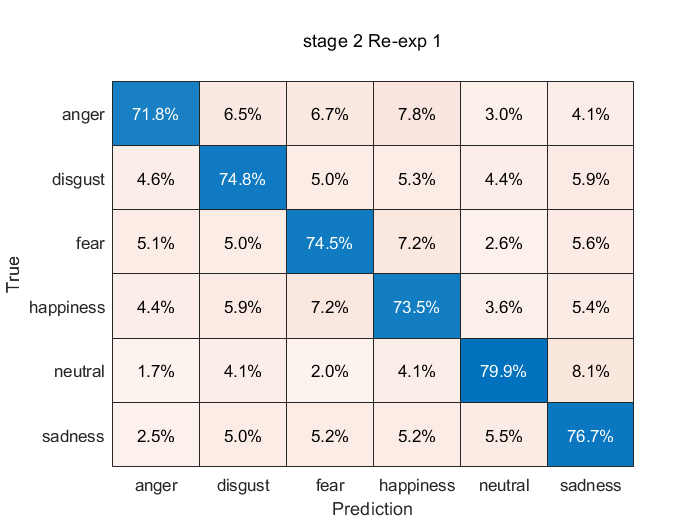

figure(2);
confusion_matrix2 = confusionchart(validationResponse,validationPredictions);
confusion_matrix2.Title = {'';'stage 2 Re-exp 1';''};
confusion_matrix2.YLabel = 'True';
confusion_matrix2.XLabel = 'Prediction';
% confusion_matrix2.RowSummary = 'row-normalized';
confusion_matrix2.Normalization = 'row-normalized';

- Average accuracy:

validationAccuracy

validationAccuracy = 0.7472

- clear

    clearvars -except response_100000_SAVEE ...
    predictors_100000_SAVEE ...
    response_100000_EMODB ...
    predictors_100000_EMODB ...
    response_100000_RAVDESS ...
    predictors_100000_RAVDESS ...
    response_test_SAVEE response_test_RAVDESS response_test_EMODB ...
    predictors_test_SAVEE predictors_test_RAVDESS predictors_test_EMODB;